#                                                                     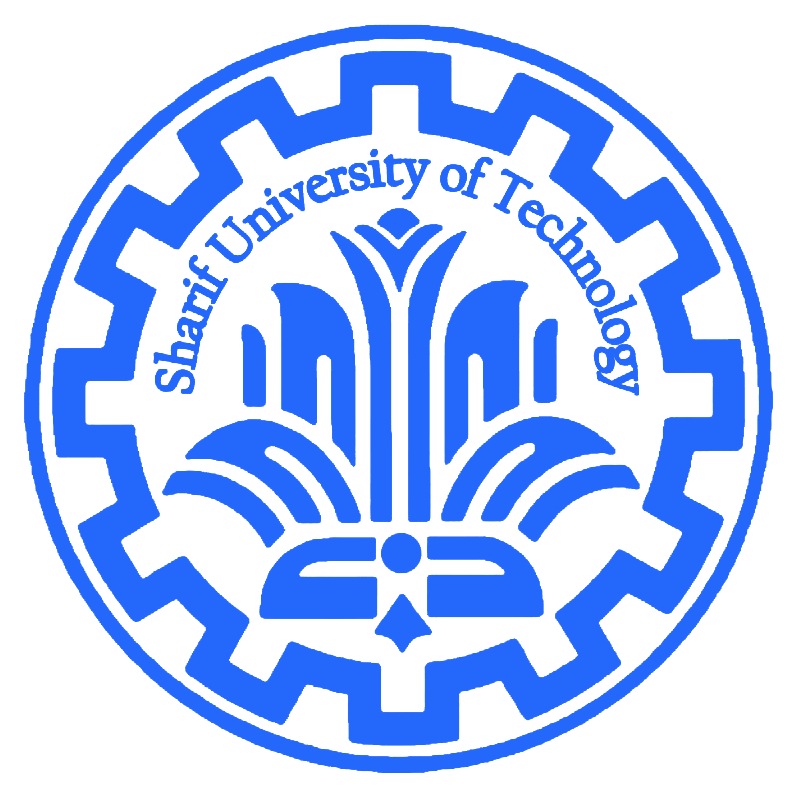

# 
$$\textbf{Stochastic Processes}
$$


# 
$$\text{Computer Assignment \#3
}
$$


#### 
$$\textit{Masoud Tahmasbi Fard - 402200275
}$$


### 
$$\textbf{Question \#3}$$


**............................................................................................................**

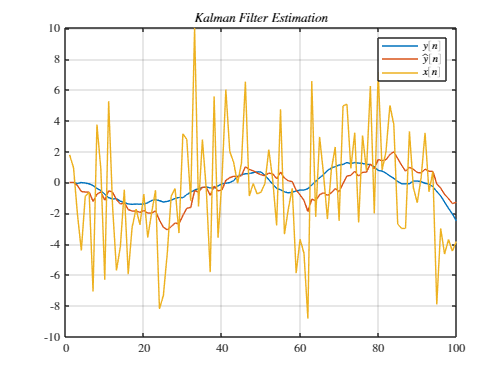

N = 100;
a1 = 1.8;
a2 = -0.81;
M = [a1,a2;1,0];
v = randn(N,1);

y = zeros(2,1);
for i=3:N
    y(i,1) = 1.8*y(i-1,1) - 0.81*y(i-2,1) + 0.1*v(i); 
end

w = randn(N,1);
x = y + sqrt(10)*w;

sigma_w = sqrt(10);
sigma_v = 0.1;

P0 = zeros(2,2);P1 = zeros(2,2);P2 = zeros(2,2);

Y0 = zeros(2,1);Y1 = zeros(2,1);Y2 = zeros(2,1);

K = zeros(2,1);
U = [sigma_v^2,0;0,0];
S = [1;0];

for i=1:N
    Y1 = M*Y0;
    P1 = M*P0*M'+ U;
    K(:,i) = (P1*S)./(S.'*P1*S + sigma_w^2);
    Y2 = Y1 + K(:,i)*(x(i)-S.'*Y1);                                                                                           
    P2 = (eye(2) - K(:,i)*S.')*P1;

    Y0 = Y2;
    P0 = P2;
end
K_final = K(:,end);

y_hat = zeros(N,1);
for i=3:N-1
    y_hat(i:i+1,1) = y_hat(i-1:i,1) + K_final*(x(i) - S.'*y_hat(i-1:i,1));
end

figure
plot(y)
hold on
plot(y_hat)
hold on
plot(x)
xlim([0,100])
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$Kalman\;Filter\;Estimation$','interpreter','latex')
legend('$y[n]$','$\hat{y}[n]$','$x[n]$','interpreter','latex')
grid on;

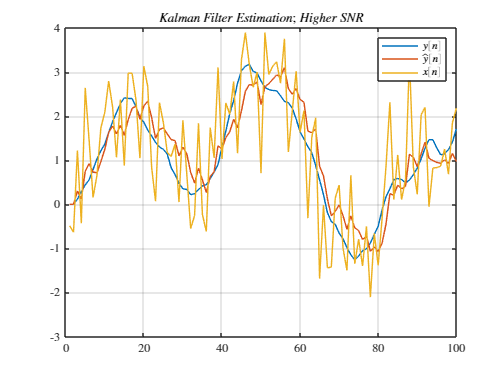

N = 100;
a1 = 1.8;
a2 = -0.81;
M = [a1,a2;1,0];
v = randn(N,1);

y = zeros(2,1);
for i=3:N
    y(i,1) = 1.8*y(i-1,1) - 0.81*y(i-2,1) + 0.1*v(i); 
end

w = randn(N,1);
x = y + 1*w;

sigma_w = 1;
sigma_v = 0.1;

P0 = zeros(2,2);P1 = zeros(2,2);P2 = zeros(2,2);

Y0 = zeros(2,1);Y1 = zeros(2,1);Y2 = zeros(2,1);

K = zeros(2,1);
U = [sigma_v^2,0;0,0];
S = [1;0];

for i=1:N
    Y1 = M*Y0;
    P1 = M*P0*M'+ U;
    K(:,i) = (P1*S)./(S.'*P1*S + sigma_w^2);
    Y2 = Y1 + K(:,i)*(x(i)-S.'*Y1);                                                                                           
    P2 = (eye(2) - K(:,i)*S.')*P1;

    Y0 = Y2;
    P0 = P2;
end
K_final = K(:,end);

y_hat = zeros(N,1);
for i=3:N-1
    y_hat(i:i+1,1) = y_hat(i-1:i,1) + K_final*(x(i) - S.'*y_hat(i-1:i,1));
end

figure
plot(y)
hold on
plot(y_hat)
hold on
plot(x)
xlim([0,100])
ax = gca;
xaxisproperties= get(ax, 'XAxis');
xaxisproperties.TickLabelInterpreter = 'latex'; 
yaxisproperties= get(ax, 'YAxis');
yaxisproperties.TickLabelInterpreter = 'latex';   
ax.XAxis.FontSize = 10;
title('$Kalman\;Filter\;Estimation;\;Higher\;SNR$','interpreter','latex')
legend('$y[n]$','$\hat{y}[n]$','$x[n]$','interpreter','latex')
grid on;